# Given Data

clear all;
clc

g=32.2;
% acceleration due to gravity in ft/s^2

Wc=505;
% weight of car in pounds

Wd=150;
% weight of driver in pounds

Wt=Wc+Wd;
% weight of car and driver in lbs

front_bias=.48;
% units in %

rear_bias=1-front_bias;
% units in %

L=60.5;
% length of car in inches

Xcg=rear_bias*L;
% horizontal distance between front tire and CG

Ycg=10.9;
% CG height in inches

V=0:5:75;
% range of velocities of the car in mph

V_fps=V*5280/3600;
% conversion from mph to fps

## Given Data (brake components)

radius_t=8;
% radius of tire in inches

mu_t=1.4;
% coefficient of friction between tire and road

mu_bf=0.60;
% coefficient of friction between front pads and rotors

mu_br=0.60;
% coefficient of friction between front pads and rotors

Pratio=6.2;
% pedal ratio
% Originally 4.7

## Front Calipers (Wilwood GP200)

radius_bf=6.57524775/2;
% perpendicular distance from center of hub to braking force on front rotor in inches
% SUBJECT TO CHANGE WITH DIFFERENT CALIPERS AND PADS

fcpiston_area=1.22718463;
% 1.25" diameter piston

fcpistons=2;
% number of pistons per caliper

fcalipers=2;
% number of calipers in front

## Rear Calipers (Wilwood GP200)

radius_br=5.86370419/2;
% perpendicular distance from center of hub to braking force on rear rotor
% SUBJECT TO CHANGE WITH DIFFERENT CALIPERS AND PADS

rcpiston_area=1.22718463;
% 1.25" diameter piston

rcpistons=2;
% number of pistons per caliper

rcalipers=2;
% number of calipers in rear

## Front Master Cylinder (Tilton 78-Series)

fMC_piston_area=0.306796158;
% (15.875 mm) piston area in in^2
% This is the 5/8" or 15.9 mm. WE HAVE THIS PART IN THE SHOP!

## Rear Master Cylinder (Tilton 78-Series)

rMC_piston_area=0.6902913545;
% 15/16" diameter piston

## Downforce

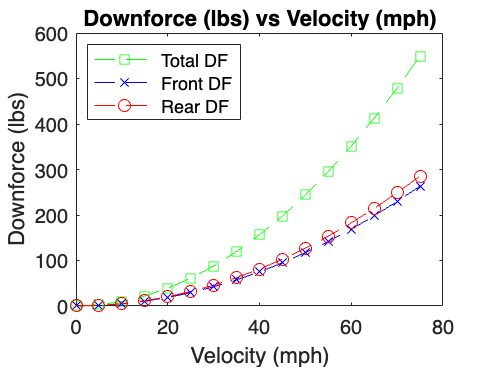

rho=.0023363397;
% rho is the air density in slug/ft^3

S=16.89934;
% surface area of wings in square feet

Cdf=2.30;
% coefficient of downforce at max downforce setting
% There are three Cdf settings (1.83, 1.88, 1.94)

DF=((1/2)*rho*V_fps.^2*S*Cdf);
% Lift Equation (lbs)

DF_fbias=.48;
% amount of DF bias in front in %

DF_rbias=1-DF_fbias;
% amount of DF bias in rear in %

DFf=DF*DF_fbias;
% amount of DF in front at specific velocities in lbs

DFr=DF*DF_rbias;
% amount of DF in rear at specific velocities in lbs

figure
plot(V,DF,'--gs',V,DFf,'--bx',V,DFr,'--ro')
xlabel('Velocity (mph)')
ylabel('Downforce (lbs)')
legend('Total DF','Front DF','Rear DF','Location','northwest')
title('Downforce (lbs) vs Velocity (mph)')

## Weight distribution (Static @ 0mph)

Wf=front_bias*Wt;
% weight on front tires in lbs

Wr=rear_bias*Wt;
% weight on rear tires in lb

## Kinetic Energy at Specific Speed Changes

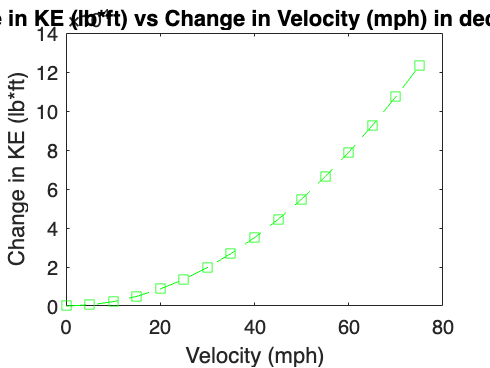

V2=0;
% final speed in mph

KE1=(Wt*V.^2)/29.9;
% initial kinetic energy in ft*lb

KE2=(Wt*V2.^2)/29.9;
% final kinetic energy in ft*lb

Kc=KE1-KE2;
% change in kinetic energy

figure
plot(V,Kc,'--gs')
xlabel('Velocity (mph)')
ylabel('Change in KE (lb*ft)')
title('Change in KE (lb*ft) vs Change in Velocity (mph) in deceleration')

## Maximum Deceleration of Car at Different Speeds Due to Downforce

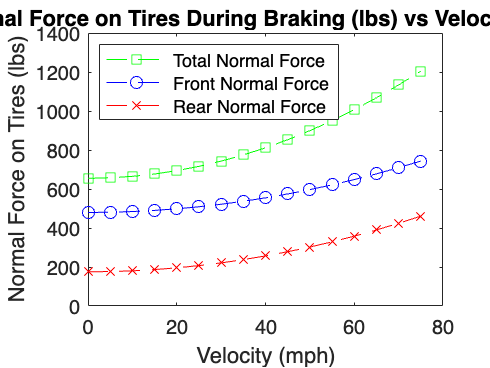

Ff=((mu_t*Wt*Ycg)/L)+((Wt*(L-Xcg))/L)+DFf;
% Normal force on front tire during max braking in lbs

Fr=((Wt*Xcg)/L)-((Wt*mu_t*Ycg)/L)+DFr;
% Normal force on front tire during max braking in lbs

Ft=Ff+Fr;
% Total normal force on all tires during max braking in lbs

figure
plot(V,Ft,'--gs',V,Ff,'--bo',V,Fr,'--rx')
xlabel('Velocity (mph)')
ylabel('Normal Force on Tires (lbs)')
title('Normal Force on Tires During Braking (lbs) vs Velocity (mph)')
legend('Total Normal Force','Front Normal Force','Rear Normal Force','Location','northwest')

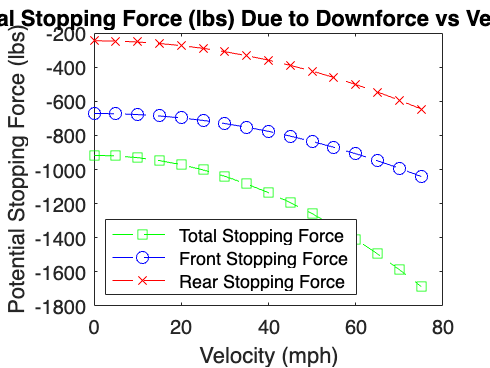


Fstopping_force=-Ff*mu_t;
Rstopping_force=-Fr*mu_t;
Tstopping_force=Fstopping_force+Rstopping_force;
% maximum potential stopping force of car in lbs

figure
plot(V,Tstopping_force,'--gs',V,Fstopping_force,'--bo',V,Rstopping_force,'--rx')
xlabel('Velocity (mph)')
ylabel('Potential Stopping Force (lbs)')
title('Potential Stopping Force (lbs) Due to Downforce vs Velocity (mph)')
legend('Total Stopping Force','Front Stopping Force','Rear Stopping Force','Location','southwest')

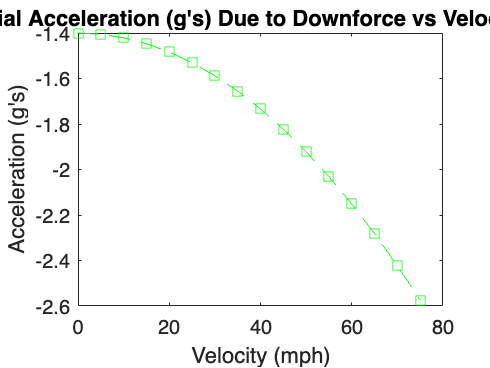


Acceleration=Tstopping_force/Wt;
% deceleration in g's

figure
plot(V,Acceleration,'--gs')
xlabel('Velocity (mph)')
ylabel('Acceleration (g''s)')
title('Potential Acceleration (g''s) Due to Downforce vs Velocity (mph)')

## Weight Transfer to front

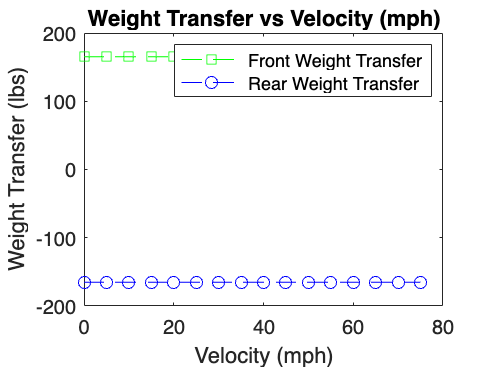

f_wt=Ff-front_bias*Wt-DFf;
% weight transfer to front tires (lbs)

r_wt=Fr-rear_bias*Wt-DFr;
% weight transfer to rear tires (lbs)

figure
plot(V,f_wt,'--gs',V,r_wt,'--bo')
xlabel('Velocity (mph)')
ylabel('Weight Transfer (lbs)')
title('Weight Transfer vs Velocity (mph)')
legend('Front Weight Transfer','Rear Weight Transfer')

## Brake bias

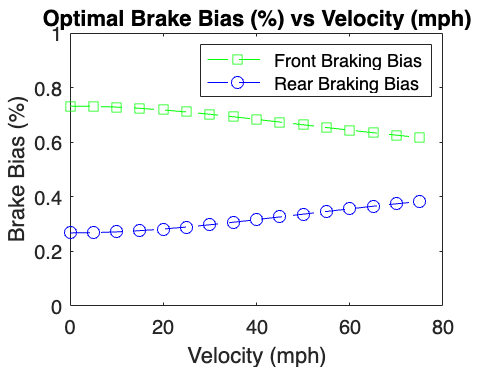

Fbrake_bias=Fstopping_force./Tstopping_force;
Rbrake_bias=1-Fbrake_bias;

figure
plot(V,Fbrake_bias,'--gs',V,Rbrake_bias,'--bo')
ylim([0 1])
xlabel('Velocity (mph)')
ylabel('Brake Bias (%)')
title('Optimal Brake Bias (%) vs Velocity (mph)')
legend('Front Braking Bias','Rear Braking Bias')

% Use brake bias @ V=0 since we first should focus on passing brake tech.
% Different bias settings may become a possibility after testing.

## Front Moment

Mf=(abs(Fstopping_force).*radius_t)/fcalipers;
% Moment about one front corner in in*lbs

## Rear Moment

Mr=(abs(Rstopping_force).*radius_t)/rcalipers;
% Moment about one rear corner in in*lbs

## Front Clamping Force

Ffb=Mf./radius_bf;
% tangential force at brake pad contact point in lbs for one front corner

clampf=Ffb./mu_bf;
% clamping force of one front caliper for one front corner

## Rear Clamping Force

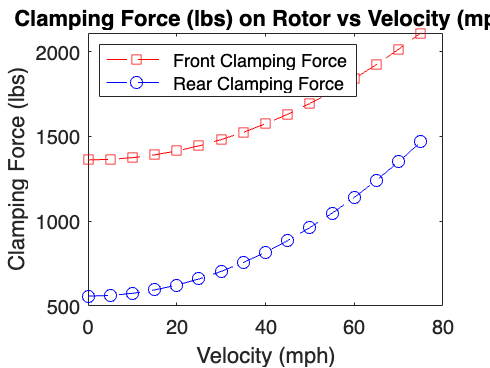

Frb=(Mr./radius_br);
% tangential force at brake pad contact point in lbs for one front corner

clampr=Frb./mu_br;
% clamping force of one rear caliper for one front corner

figure
plot(V,clampf,'--rs',V,clampr,'--bo')
xlabel('Velocity (mph)')
ylabel('Clamping Force (lbs)')
title('Clamping Force (lbs) on Rotor vs Velocity (mph)')
legend('Front Clamping Force','Rear Clamping Force','Location','northwest')

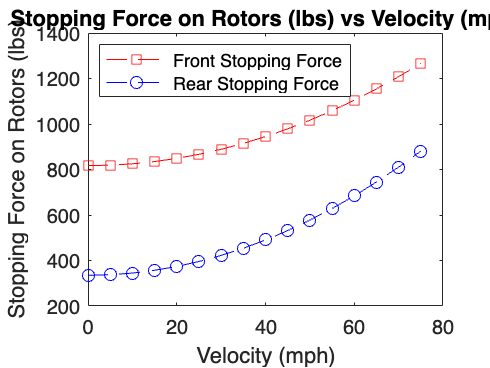


figure
plot(V,Ffb,'--rs',V,Frb,'--bo')
xlabel('Velocity (mph)')
ylabel('Stopping Force on Rotors (lbs)')
title('Stopping Force on Rotors (lbs) vs Velocity (mph)')
legend('Front Stopping Force','Rear Stopping Force','Location','northwest')

## Front Brake Pressure

Pf=clampf./(fcpistons*fcpiston_area);
% pressure in front brake lines

## Rear Brake Pressure

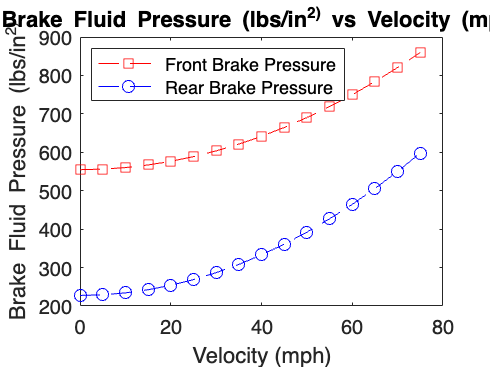

Pr=clampr./(rcpistons*rcpiston_area);
% pressure in rear brake lines

figure
plot(V,Pf,'--rs',V,Pr,'--bo')
xlabel('Velocity (mph)')
ylabel('Brake Fluid Pressure (lbs/in^2)')
title('Brake Fluid Pressure (lbs/in^2) vs Velocity (mph)')
legend('Front Brake Pressure','Rear Brake Pressure','Location','northwest')

## Front Master Cylinder

Fmc=(clampf.*fMC_piston_area)./(fcpistons*fcpiston_area);
% required master cylinder input force in lbs to lock front tires

## Rear Master Cylinder Force

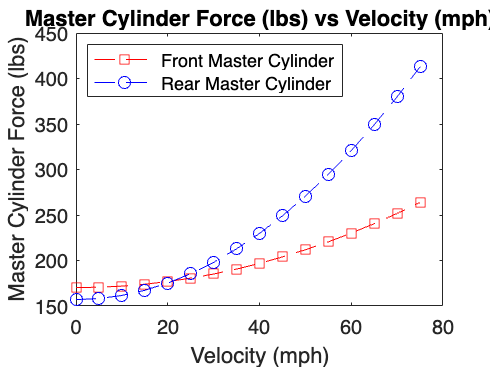

Rmc=(clampr.*rMC_piston_area)./(rcpistons*rcpiston_area);
% required master cylinder input force in lbs to lock rear tires

figure
plot(V,Fmc,'--rs',V,Rmc,'--bo')
xlabel('Velocity (mph)')
ylabel('Master Cylinder Force (lbs)')
title('Master Cylinder Force (lbs) vs Velocity (mph)')
legend('Front Master Cylinder','Rear Master Cylinder','Location','northwest')

## Pedal Force Absorbing Momentum of Driver

pedal_input_momentum=abs((Wd/g).*Acceleration);
% Force on pedal from driver's moentum in lbs

## Driver Input Force to Lock Tires

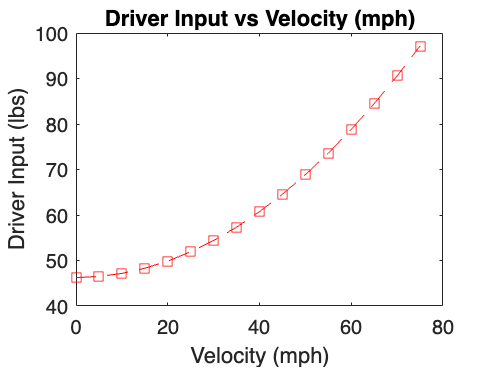

Tmc=Fmc+Rmc;
% Total input force at master cylinders to lock the tires

pedal_force=Tmc./Pratio;
% Input force from driver in lbs

driver_input=pedal_force-pedal_input_momentum;
% Input from driver in lbs (not including momentum)

figure
plot(V,driver_input,'--rs')
xlabel('Velocity (mph)')
ylabel('Driver Input (lbs)')
title('Driver Input vs Velocity (mph)')

## Plots for All Brake Components in One Subplot

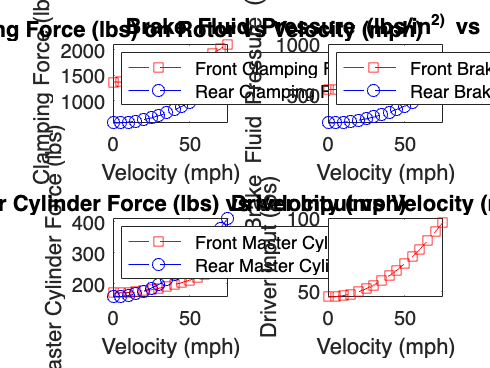

subplot(2,2,1)
plot(V,clampf,'--rs',V,clampr,'--bo')
xlabel('Velocity (mph)')
ylabel('Clamping Force (lbs)')
title('Clamping Force (lbs) on Rotor vs Velocity (mph)')
legend('Front Clamping Force','Rear Clamping Force','Location','northwest')

subplot(2,2,2)
plot(V,Pf,'--rs',V,Pr,'--bo')
xlabel('Velocity (mph)')
ylabel('Brake Fluid Pressure (lbs/in^2)')
title('Brake Fluid Pressure (lbs/in^2) vs Velocity (mph)')
legend('Front Brake Pressure','Rear Brake Pressure','Location','northwest')

subplot(2,2,3)
plot(V,Fmc,'--rs',V,Rmc,'--bo')
xlabel('Velocity (mph)')
ylabel('Master Cylinder Force (lbs)')
title('Master Cylinder Force (lbs) vs Velocity (mph)')
legend('Front Master Cylinder','Rear Master Cylinder','Location','northwest')

subplot(2,2,4)
plot(V,driver_input,'--rs')
xlabel('Velocity (mph)')
ylabel('Driver Input (lbs)')
title('Driver Input vs Velocity (mph)')

## Power

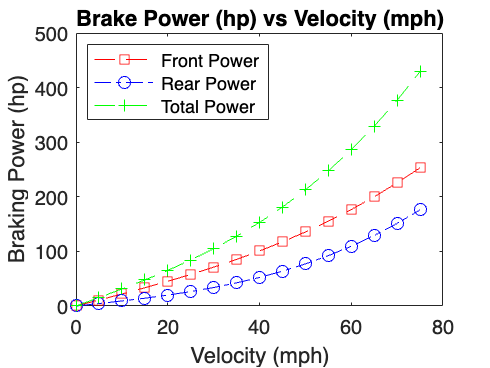

rpmf=(V.*88)/(2*pi*radius_bf);

rpmr=(V.*88)/(2*pi*radius_br);

Pwr_f=(Mf.*rpmf)./5252;

Pwr_r=(Mr.*rpmr)./5252;

Pwr_t=Pwr_f+Pwr_r;

figure
plot(V,Pwr_f,'--rs',V,Pwr_r,'-.bo',V,Pwr_t,'--g+')
xlabel('Velocity (mph)')
ylabel('Braking Power (hp)')
title('Brake Power (hp) vs Velocity (mph)')
legend('Front Power','Rear Power','Total Power','Location','northwest')

## Pedal Force vs Deceleration

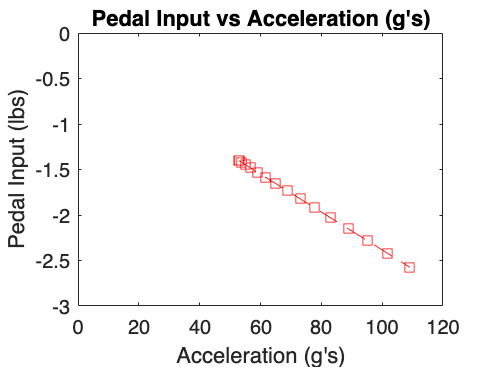

figure
plot(pedal_force,Acceleration,'--rs')
xlim([0 120])
ylim([-3 0])
xlabel('Acceleration (g''s)')
ylabel('Pedal Input (lbs)')
title('Pedal Input vs Acceleration (g''s)')

## Pedal Force vs Brake Pressure

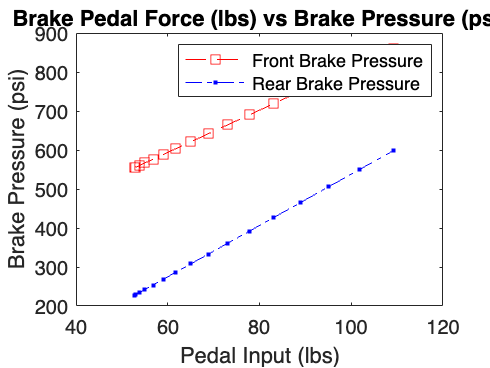

figure
plot(pedal_force,Pf,'--rs',pedal_force,Pr,'-.b.')
xlabel('Pedal Input (lbs)')
ylabel('Brake Pressure (psi)')
legend('Front Brake Pressure', 'Rear Brake Pressure')
title('Brake Pedal Force (lbs) vs Brake Pressure (psi)')

## Brake Pressure vs Deceleration

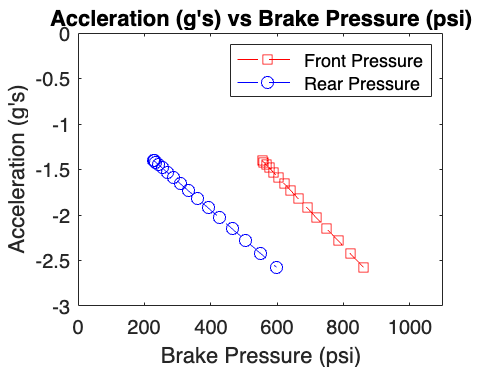

figure
plot(Pf,Acceleration,'--rs',Pr,Acceleration,'--bo')
ylim([-3 0])
xlim([0 1100])
xlabel('Brake Pressure (psi)')
ylabel('Acceleration (g''s)')
title('Accleration (g''s) vs Brake Pressure (psi)')
legend('Front Pressure','Rear Pressure')

## Rear Pressure vs Front Pressure

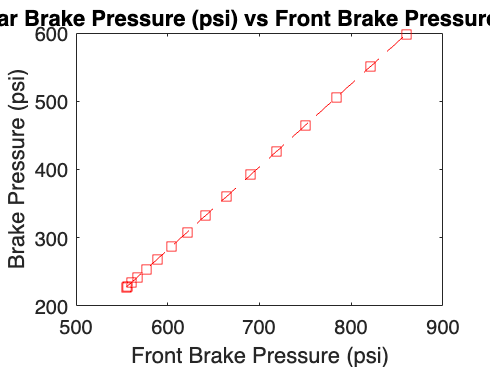

figure
plot(Pf,Pr,'--rs')
xlabel('Front Brake Pressure (psi)')
ylabel('Brake Pressure (psi)')
title('Rear Brake Pressure (psi) vs Front Brake Pressure (psi)')